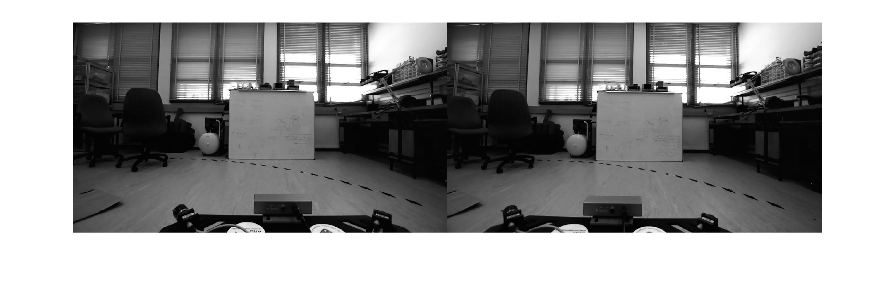

I1 = imread("Experiment_1\left\left_image_10.jpg");
I2 = imread("Experiment_1\right\right_image_10.jpg");

% Convert to grayscale.
I1gray = rgb2gray(I1);
I2gray = rgb2gray(I2);

figure
imshowpair(I1gray, I2gray, "montage")

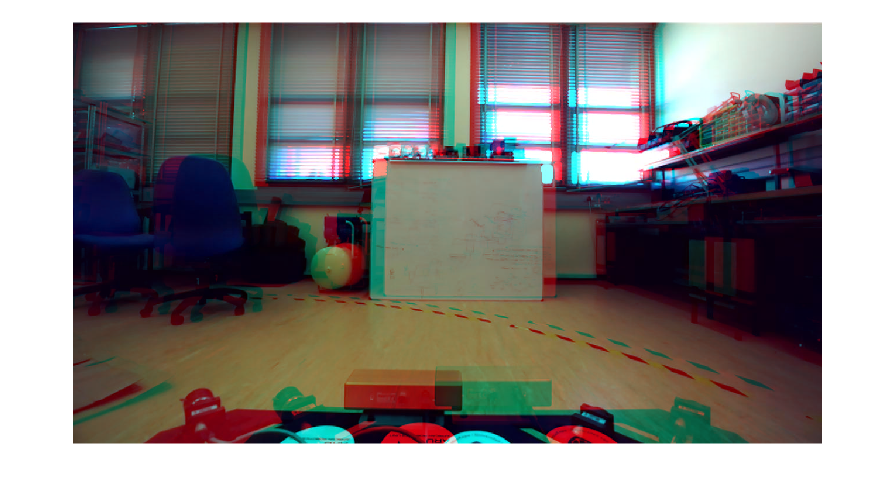

figure 
imshow(stereoAnaglyph(I1, I2))

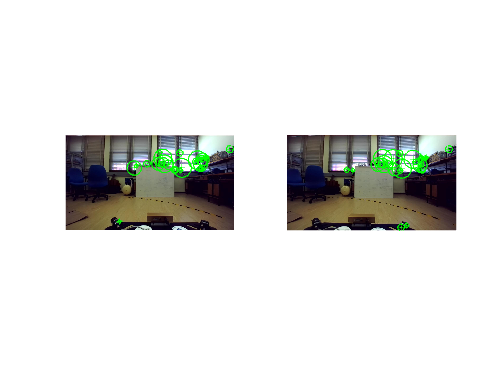


% Assuming I1, I2, blobs1, and blobs2 are already defined
blobs1 = detectSURFFeatures(I1gray, 'MetricThreshold', 2000);
blobs2 = detectSURFFeatures(I2gray, 'MetricThreshold', 2000);

figure;
% Display the first image with features
subplot(1, 2, 1); % 1 row, 2 columns, first subplot
imshow(I1);
hold on;
plot(selectStrongest(blobs1, 30));

% Display the second image with features
subplot(1, 2, 2); % 1 row, 2 columns, second subplot
imshow(I2);
hold on;
plot(selectStrongest(blobs2, 30));

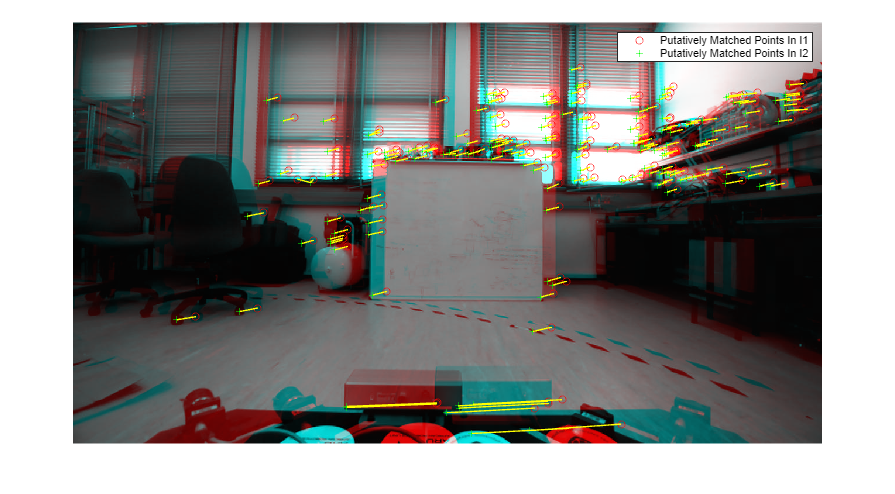


[features1, validBlobs1] = extractFeatures(I1gray, blobs1);
[features2, validBlobs2] = extractFeatures(I2gray, blobs2);
indexPairs = matchFeatures(features1, features2, 'Metric', "SAD", ...
    'MatchThreshold', 5);
matchedPoints1 = validBlobs1(indexPairs(:, 1), :);
matchedPoints2 = validBlobs2(indexPairs(:, 2), :);

figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1", "Putatively Matched Points In I2")

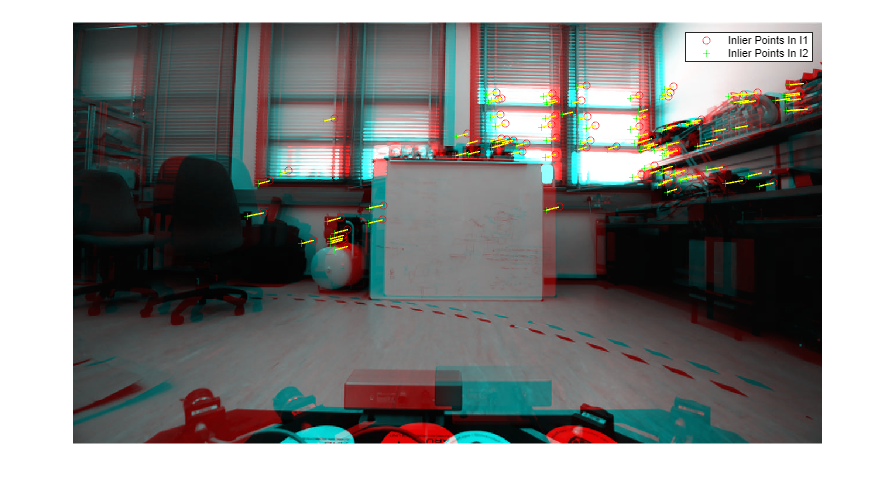


[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
    matchedPoints1, matchedPoints2, 'Method', "RANSAC", ...
    'NumTrials', 10000, 'DistanceThreshold', 0.1, 'Confidence', 99.99);

if status ~= 0 || isEpipoleInImage(fMatrix, size(I1)) ...
    || isEpipoleInImage(fMatrix', size(I2))
    error(["Not enough matching points were found or "...
        "the epipoles are inside the images. Inspect "...
        "and improve the quality of detected features ",...
        "and images."]);
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1", "Inlier Points In I2")

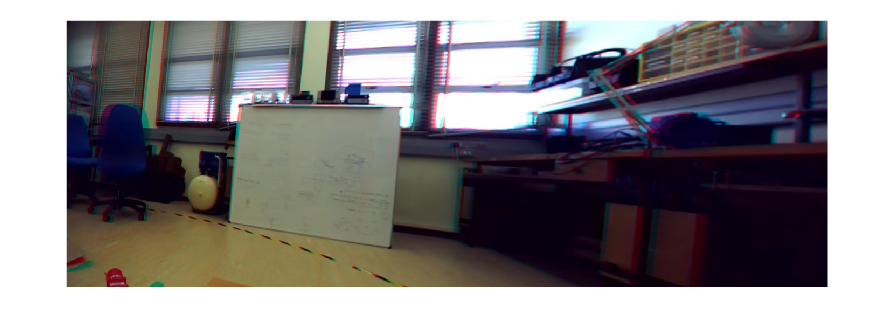


[tform1, tform2] = estimateStereoRectification(fMatrix, ...
    inlierPoints1.Location, inlierPoints2.Location, size(I2));
[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, tform1, tform2);

% Save the rectified stereo images
outputFolder = 'stereoRect_1'; % Name of the folder to save images
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

imwrite(I1Rect, fullfile(outputFolder, 'I1Rect.jpg'));
imwrite(I2Rect, fullfile(outputFolder, 'I2Rect.jpg'));

figure
imshow(stereoAnaglyph(I1Rect, I2Rect))

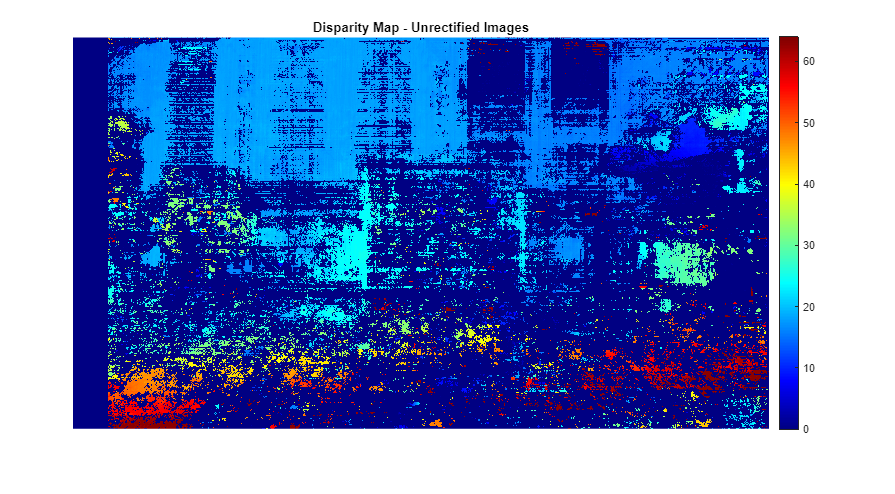


% Compute disparity map for unrectified images
disparityRange = [0, 64];
disparityMapUnrect = disparitySGM(I1gray, I2gray, 'DisparityRange', disparityRange);
figure
imshow(disparityMapUnrect, disparityRange)
title('Disparity Map - Unrectified Images')
colormap jet
colorbar

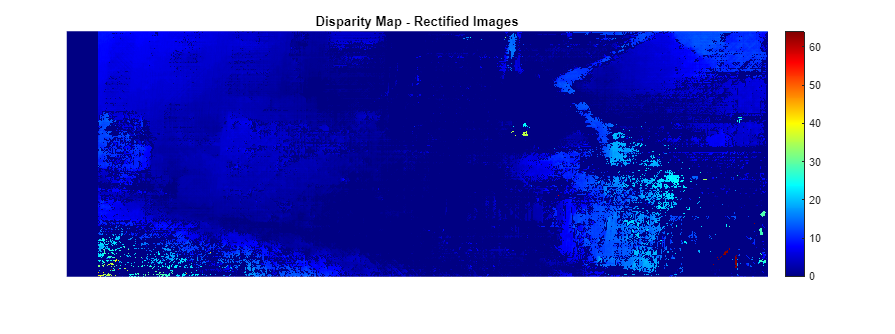


% Compute disparity map for rectified images
I1RectGray = rgb2gray(I1Rect);
I2RectGray = rgb2gray(I2Rect);
disparityMapRect = disparitySGM(I1RectGray, I2RectGray, 'DisparityRange', disparityRange);
figure
imshow(disparityMapRect, disparityRange)
title('Disparity Map - Rectified Images')
colormap jet
colorbar

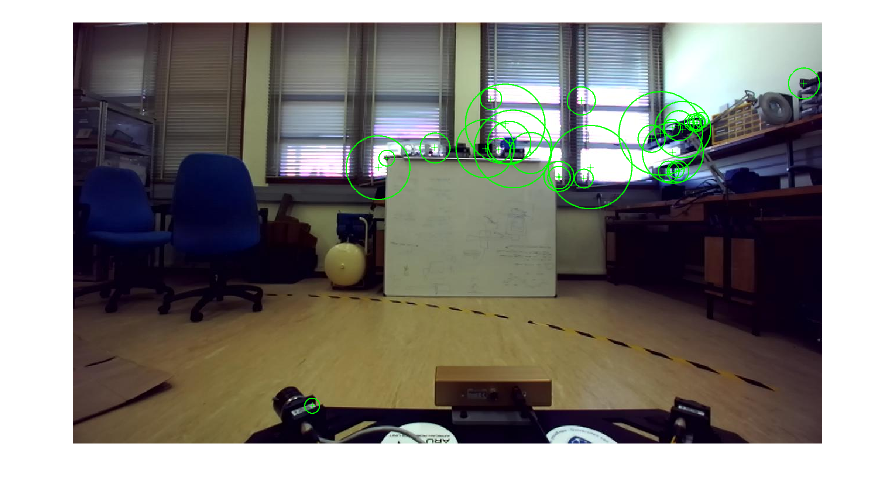

figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1,30))

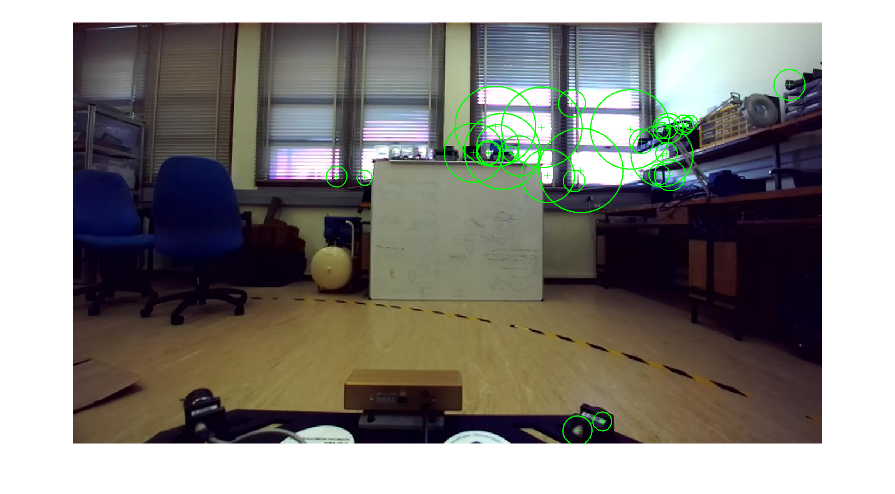



figure
imshow(I2)
hold on
plot(selectStrongest(blobs2,30))